# Exercise 1.1 - Tinkering with audio files

## Signal #1 (violin)

% Load in the audio file signal. 
[violin, fs1] = audioread('audio\violin.wav');
 
% Play the signal.
sound(violin,  fs1);
 
% Print out the sampling frequency. 
fs1

fs1 = 44100

 
% Print out information about the audio fragment. It is extracted from 
% the struct info1 that the duration is 5 s.
info1 = audioinfo('audio\violin.wav')

info1 = struct with fields:
             Filename: 'C:\Users\abi\Desktop\ITDS\_pract\pract_01\audio\violin.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 220500
             Duration: 5
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


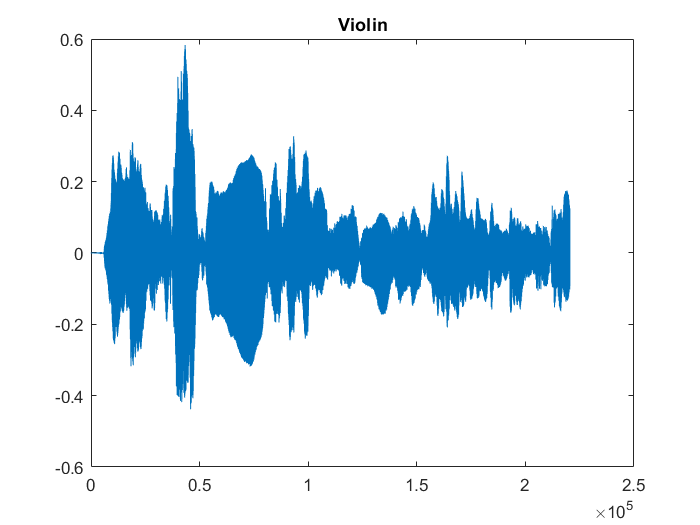


% Represent the signal in the time domain. It is observed that the signal
% is not periodic, since the expression x[n + N] = x[n] is not verified,
% where N is the hypothetical period.
plot(violin);
title('Violin');

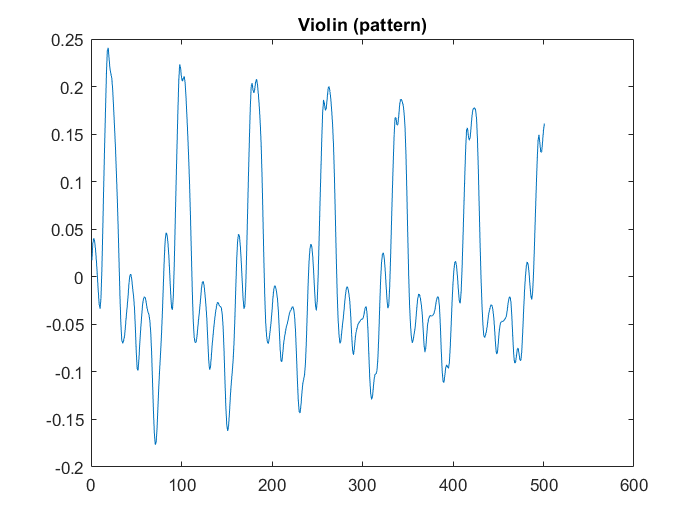


% Note that, by taking an even smaller fragment and plotting it, we get a
% pattern, representative of the harmonics series of this particular
% violin, and therefore, its musical timbre (making it different from others).
% That is to say that it is an in-harmonic instrument.
plot(violin(100000 : 100500));
title('Violin (pattern)');

## Signal #2 (knocking) 

% The process is exactly the same as that of the previous signal.
[knocking, fs2] = audioread('audio\knocking.wav');

% Uncomment and comment the other sound functions from the other signals to
% avoid overlapping while running the program.
%sound(knocking, fs2);

fs2

fs2 = 8000


% It is extracted from the struct info2 that the duration is 1.8 s.
info2 = audioinfo('audio\knocking.wav')

info2 = struct with fields:
             Filename: 'C:\Users\abi\Desktop\ITDS\_pract\pract_01\audio\knocking.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8000
         TotalSamples: 14400
             Duration: 1.8000
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


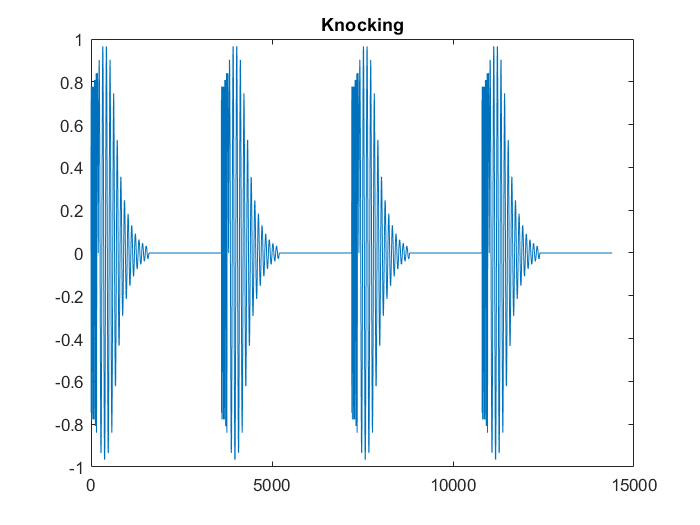


plot(knocking);
title('Knocking');

## Signal #3 (kitty) 

[kitty, fs3] = audioread('audio\kitty.wav');

% Uncomment and comment the other sound functions from the other signals to
% avoid overlapping while running the program.
%sound(kitty, fs3);

fs3

fs3 = 11025


% It is extracted from the struct info3 that the duration is ≈ 1.42.
info3 = audioinfo('audio\kitty.wav')

info3 = struct with fields:
             Filename: 'C:\Users\abi\Desktop\ITDS\_pract\pract_01\audio\kitty.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 11025
         TotalSamples: 15642
             Duration: 1.4188
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 8


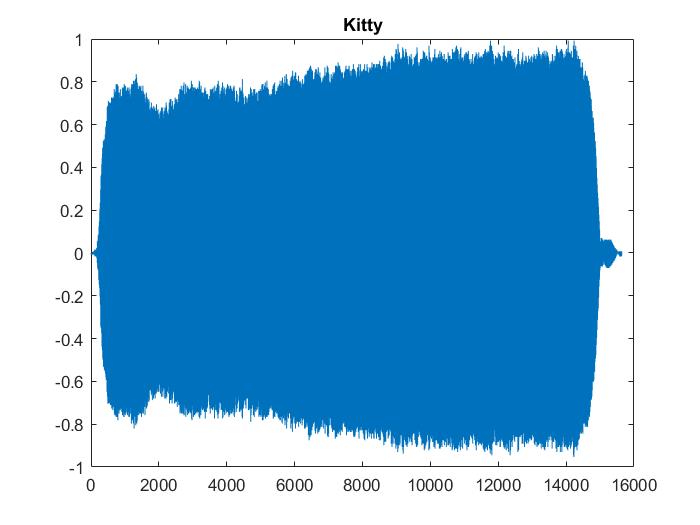


plot(kitty);
title('Kitty');